# Otto Efficiency

**Goal:** Some thermodyanic parameters such as specific heat of the air-fuel mixture affect the Otto cycle. The parameter values need to be reasonable to keep the cycle reasonable. Let's check that in this Live Script.

**Reference:** [EN14] Eriksson, Nielsen, "*Modeling and Control of Engines and Drivelines*", Wiley (2014)

## Description

In the isentropic (adiabatic and reversible) process, the following polytropic relationship holds: 

EN14-(5.1): $\frac{p_2 }{p_1 }={\left(\frac{v_1 }{v_2 }\right)}^{\gamma \;} =r_c^{\gamma \;}$

EN14-(5.2): $\frac{T_2 }{T_1 }={\left(\frac{v_1 }{v_2 }\right)}^{\gamma -1} =r_c^{\gamma -1}$

where $\gamma \;$is the specific heat ratio $\gamma =\frac{c_p }{c_v }$, $r_c$is the compression ratio.

The general form of combustion cycle efficiency (see 5.2.2 *Derivation of Cycle Efficiencies* in [EN14]) is


$$\eta =\frac{q_{\mathrm{in}} -q_{\mathrm{loss}} }{q_{\mathrm{in}} }=1-\frac{q_{\mathrm{loss}} }{q_{\mathrm{in}} }$$


where, in the Otto cycle, $q_{\mathrm{in}} =c_v \left(T_3 -T_2 \right)$ and $q_{\mathrm{loss}} =c_v \left(T_4 -T_1 \right)$.

In the Model 7.16 (*Analytical In-cylinder Pressure Model* in [EN14]), two different specific heat ratio $k_c$ and $k_e$ are used for compression and expansion processes, respectively (see 7.8.1 *Compression Asymptote* and 7.8.2 *Expansion Asymptote* in [EN14]). This means that there exist two different specific heat capacities $c_{v,c}$ and $c_{v,e}$ in Model 7.16. In $q_{\mathrm{in}} =c_v \left(T_3 -T_2 \right)$, let us use compression cycle's $c_{v,c}$ for $c_v$. Likewise, let us use $c_{v,e}$ in $q_{\mathrm{loss}}$.


$$\eta {\;}_{\mathrm{Otto}} =1-\frac{q_{\mathrm{loss}} }{q_{\mathrm{in}} }=1-\frac{c_{v,e} }{c_{v,c} }\cdot \frac{T_4 -T_1 }{T_3 -T_2 }$$


Under isentropic compression and expansion EN14-(5.2) with Model 7.16's compression and expansion process distinction, we apply $T_3 =T_4 r_c^{\gamma_e -1}$ and $T_2 =T_1 r_c^{\gamma_c -1}$ in $\eta {\;}_{\mathrm{Otto}}$ above.


$$\eta {\;}_{\mathrm{Otto}} =1-\frac{c_{v,e} }{c_{v,c} }\cdot \frac{1-\frac{T_1 }{T_4 }}{r_c^{\gamma {\;}_e -1} -r_c^{\gamma {\;}_c -1} \cdot \frac{T_1 }{T_4 }}$$


This corresponds to EN14-(5.7), but rather different due to the consideration of Model 7.16. On R.H.S. of the above formula, $\frac{T_1 }{T_4 }$ is the only variable while all the other symbols are treated as constant. Since $0<T_1 <T_4$, the value range of $\frac{T_1 }{T_4 }$is between 0 and 1.

## Parameters

% compression ratio
rc = paramfcn_cylinder_CompRatio()

rc = 12.5000

% specific heat ratio for compression polytropic process
k_c = paramfcn_cylinder_gas_Gamma_compression()

k_c = 1.2500

% specific heat ratio for expansion polytropic process
k_e = paramfcn_cylinder_gas_Gamma_expansion()

k_e = 1.3000

% constant volume specific heat for compression polytropic process
cv_c = paramfcn_cylinder_gas_Cv_comp_J_perkg_perK()

cv_c = 1.1528e+03

% constant volume specific heat for expansion polytropic process
cv_e = paramfcn_cylinder_gas_Cv_exp_J_perkg_perK()

cv_e = 960.6549

Check that $k_e >k_c$ holds. This is required to keep the efficiency value range between 0 and 1.

assert( k_e > k_c )

## Inputs

% x = T1/T4
x = transpose(linspace(0.1, 1.0, 100));

## Equations

Otto Efficiency

eta_Otto = 1 - cv_e/cv_c * (1 - x)./( rc^(k_e - 1) - rc^(k_c - 1) .* x );

## Plot

Check that the efficiency is between 0 and 1. For the standard analysis of Otto cycle efficiency, see 5.2.2 *Derivation of Cycle Efficiencies* in [EN14], especially see Figure 5.6 in page 90 for the plot.

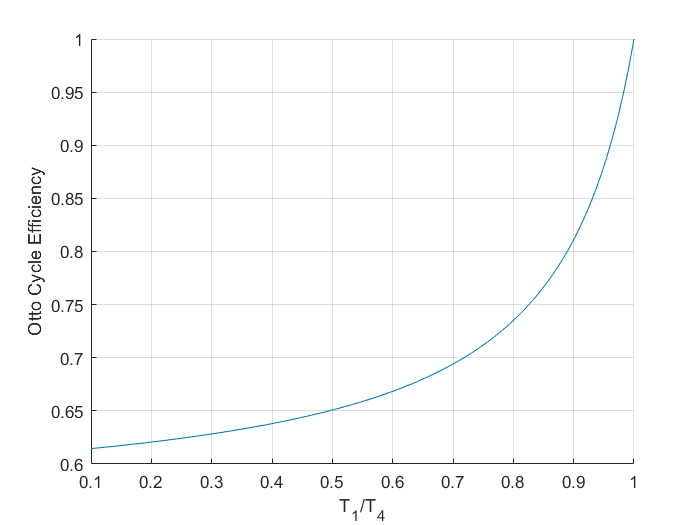

figure;  hold on;  grid on
plot(x, eta_Otto)
xlabel('T_1/T_4')
ylabel('Otto Cycle Efficiency')